data = readtable('jump_data_1.csv');
data

data = 978×5 table
        t            a_x        a_y        a_z       a_abs 
    __________    _________    ______    ________    ______

    0.00086267     0.074545    9.3975    -0.25956    9.4013
      0.010942      0.30851    9.4518    -0.06721    9.4571
      0.021022      0.37467    9.4048     0.40551     9.421
      0.031101       0.2419    9.2903     0.83766    9.3311
       0.04118     -0.14535    9.0565      1.1498    9.1303
      0.051259     -0.47302    8.8459      1.2523    8.9466
      0.061339     -0.44068    8.7873      1.2177    8.8822
      0.071418    -0.060474    8.8945      1.0662    8.9584
      0.081497     0.026645    8.9244     0.80443    8.9607
      0.091577      0.43709     8.773     0.40626    8.7932
       0.10166      0.33725    8.7848     0.49517    8.8052
       0.11173      0.41748   

time_range = 200:900

time_range =    200   201   202   203   204   205   206   207   208   209   210   211   212   213   214   215   216   217   218   219   220   221   222   223   224   225   226   227   228   229   230   231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248   249


t_trim = data.t(time_range)

t_trim =     2.0066
    2.0167
    2.0268
    2.0369
    2.0470
    2.0570
    2.0671
    2.0772
    2.0873
    2.0974


a_y_trim = data.a_y(time_range)

a_y_trim =    14.9184
   19.9574
   26.4186
   33.5635
   39.2077
   40.3838
   38.8071
   37.2173
   35.7816
   34.0112


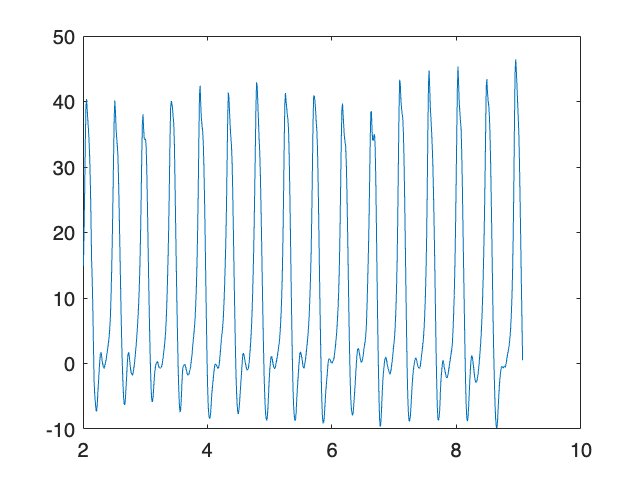

plot(t_trim, a_y_trim)

dftx = fft(a_y_trim);

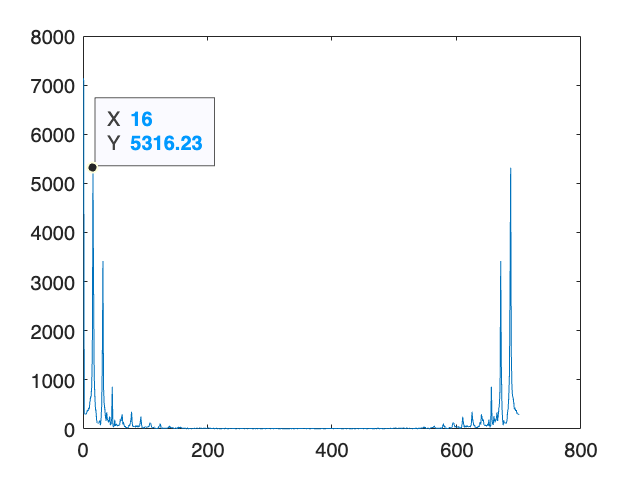

plot(abs(dftx))